# Testing Different Backoff Protocols

## Linear Backoff 

W1 = 2; W2 = 3; W3 = 4; etc.

The size of the window increases linearly each timestep

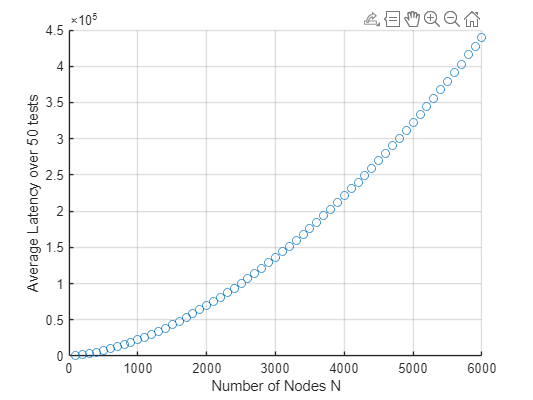

n = 100:100:6000; % number of devices connecting to network
latencyArr = zeros(10, length(n)); 

% run tests 10 times each to get average
for X = 1:50
    % run the test for each number of devices in n
    for N = 1:length(n)
        n_temp = n(N);
        latency = 0;
        window = 2;
        
        % run until all devices succeed
        while true
            % generate <n_temp> random numbers between 
            % 0 and window size
            device = randi([0, window], 1, n_temp);
            
            % determine number of devices at each random number
            % and remove the number of devices that succeeded
            succeeded = histcounts(device, 0:window+1); 
            n_temp = n_temp - sum(succeeded == 1);
            
            % increment the latency
            latency = latency + window;
            
            % break if there are no more devices
            if n_temp <= 0
                break
            end

            % increment the window size by one since it's linear
            window = window + 1;
        end
        % append the latency for this test number and
        % current device number
        latencyArr(X, N) = latency;
    end
end

% find the average for each device number
linearBackoff = mean(latencyArr, 1);

% plot the number of devices vs latency in a scatter plot
scatter(n, linearBackoff)
grid on
xlabel("Number of Nodes N")
ylabel("Average Latency over 50 tests")

## Binary Exponential Backoff

W1 = 2; W2 = 4; W3 = 8; etc.

The size of the window increases to the next binary exponential each timestep

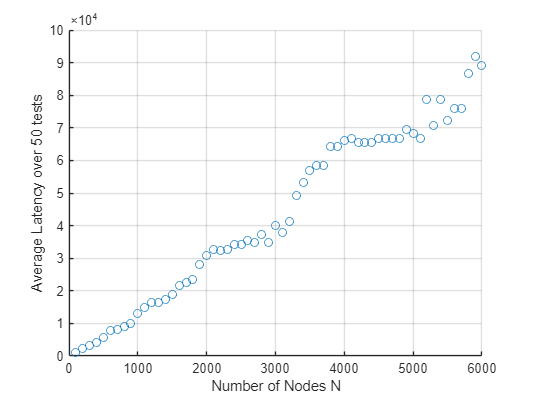

n = 100:100:6000; % number of devices connecting to network
latencyArr = zeros(10, length(n));

for X = 1:50
    for N = 1:length(n)
        n_temp = n(N);
        latency = 0;
        window = 2;
        temp = 2;

        while true
            % generate <n_temp> random numbers between 
            % 0 and window size
            device = randi([0, window], 1, n_temp); 
            
            % determine number of devices at each random number
            % and remove the number of devices that succeeded
            succeeded = histcounts(device, 0:window+1); 
            n_temp = n_temp - sum(succeeded == 1);
            
            % increment the latency
            latency = latency + window;
            
            % break if there are no more devices
            if n_temp <= 0
                break
            end

            % increment the window to the next binary exponential number
            window = 2^temp;
            temp = temp + 1;
        end
     % append the latency for this test number and
        % current device number
        latencyArr(X, N) = latency;
    end
end

% find the average for each device number
binaryExponentialBackoff = mean(latencyArr, 1);

% plot the number of devices vs latency in a scatter plot
scatter(n, binaryExponentialBackoff)
grid on
xlabel("Number of Nodes N")
ylabel("Average Latency over 50 tests")

## LogLog Backoff

W1 = 4; W2 = (1+1/(log(log(W1))*W1 = 8; W3 = (1+1/(log(log(W2))*W2 = 13; etc.

The size of the window increases in a loglog fashion each timestep

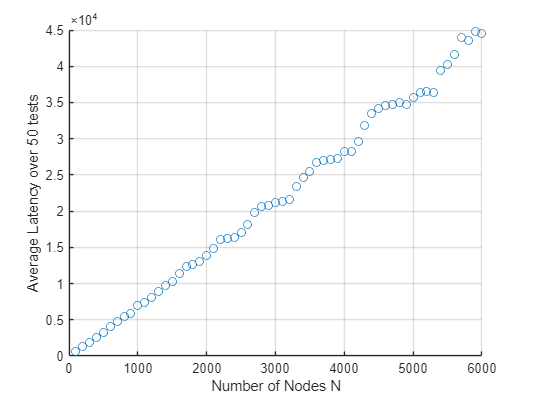

n = 100:100:6000; % number of devices connecting to network
latencyArr = zeros(10, length(n));

for X = 1:50
    for N = 1:length(n)
        n_temp = n(N);
        latency = 0;
        window = 4;

        while true
            % generate <n_temp> random numbers between 
            % 0 and window size
            device = randi([0, window], 1, n_temp); 
            
            % determine number of devices at each random number
            % and remove the number of devices that succeeded
            succeeded = histcounts(device, 0:window+1); 
            n_temp = n_temp - sum(succeeded == 1);
            
            % increment the latency
            latency = latency + window;
            
            % break if there are no more devices
            if n_temp <= 0
                break
            end

            % increment the window using the loglog formula
            window = floor((1+1/log2(log2(window)))*window);
        end
     % append the latency for this test number and
        % current device number
        latencyArr(X, N) = latency;
    end
end

% find the average for each device number
logLogBackoff = mean(latencyArr, 1);

% plot the number of devices vs latency in a scatter plot
scatter(n, logLogBackoff)
grid on
xlabel("Number of Nodes N")
ylabel("Average Latency over 50 tests")

## Plot all of them together

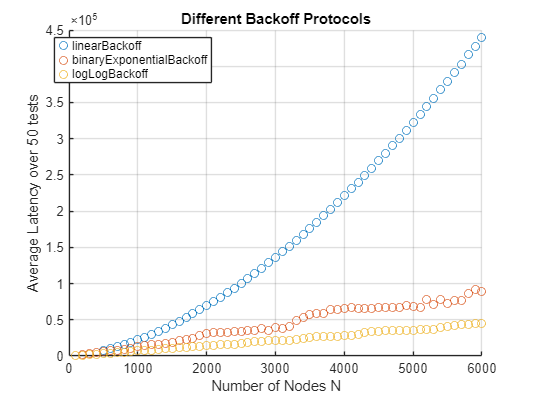

tbl = table(n, linearBackoff, binaryExponentialBackoff, logLogBackoff);
scatter(tbl, 'n', {'linearBackoff', 'binaryExponentialBackoff', 'logLogBackoff'})
grid on
legend("Position",[.1, .8, .3, .1])
xlabel("Number of Nodes N")
ylabel("Average Latency over 50 tests")
title("Different Backoff Protocols")